clc
clear
close all
% Cargar los datos desde Excel (se debe ajustar el nombre del archivo)
filename = 'Datos_aceite_motor.xlsx';

% Leer cada bloque de columnas
med_oscuro = readmatrix(filename, 'Range', 'V4:W104');   % Se ajusta el rango si se tienen más datos
med_constante = readmatrix(filename, 'Range', 'X4:Y1185');
mediciones = readmatrix(filename, 'Range', 'Z4:AA1403');


## Grafico 1

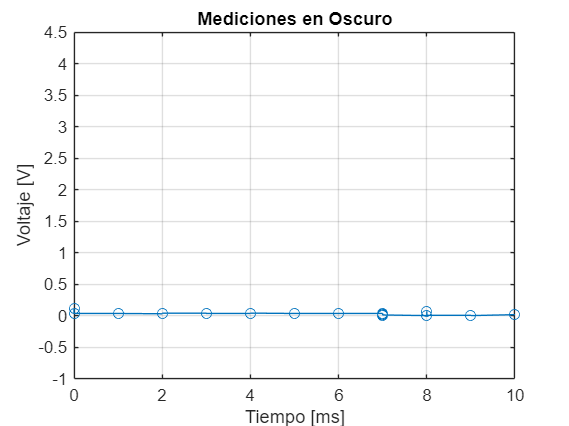

% Separar columnas
tiempo_osc = med_oscuro(:,1);
voltaje_osc = med_oscuro(:,2);

% Agrupar por tiempo si es necesario, o solo graficar todos
figure;
plot(tiempo_osc, voltaje_osc, 'o-');
xlabel('Tiempo [ms]');
ylabel('Voltaje [V]');
title('Mediciones en Oscuro');
ylim([-1 4.5]);           % Ajustar escala del eje Y
grid on;

## Grafico 2

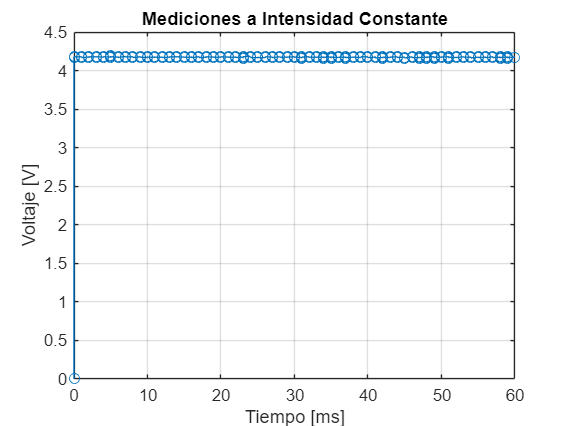

tiempo_const = med_constante(:,1);
voltaje_const = med_constante(:,2)/1000;

figure;
plot(tiempo_const, voltaje_const, 'o-');
xlabel('Tiempo [ms]');
ylabel('Voltaje [V]');
title('Mediciones a Intensidad Constante');
ylim([0 4.5]);           % Ajustar escala del eje Y
grid on;

## Grafico 3

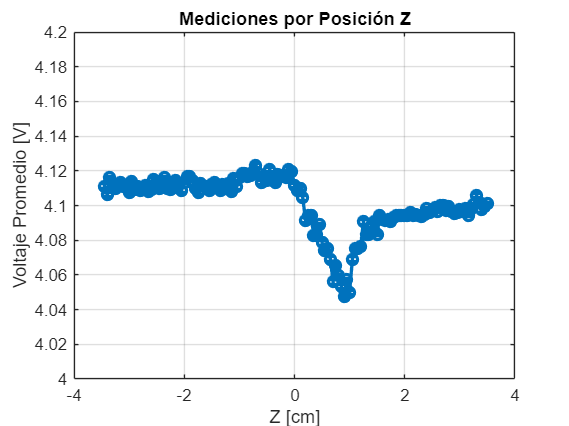

Z = mediciones(:,1);
V = mediciones(:,2)/1000;

% Encontrar los valores únicos de Z (posiciones)
Z_unicos = unique(Z);

promedios = zeros(length(Z_unicos), 1);
errores = zeros(length(Z_unicos), 1);

for i = 1:length(Z_unicos)
    idx = Z == Z_unicos(i);
    voltajes_z = V(idx);
    promedios(i) = mean(voltajes_z);
    errores(i) = std(voltajes_z) / sqrt(length(voltajes_z)); %error estándar
end

figure;
errorbar(Z_unicos, promedios, errores, 'o-', 'LineWidth', 2);
xlabel('Z [cm]');
ylabel('Voltaje Promedio [V]');
title('Mediciones por Posición Z');
ylim([4 4.2]);           % Ajustar escala del eje Y
grid on;

## Guardar

%saveas(gcf, 'grafico_z.png');